% load experiment and replace units with new sorting
experiment.Units = sorted_from_phy('/lampllab/Data/Awake_AP2.5_ML4.0_A1/FVB/301121/986/kilosort/');
experiment.evokedEvents = experiment.getEvoked

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB108_986'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: []


% Find whisking epochs
[b,a] = cheby1(5,20,[15]/200,'low');
mot_filt = filtfilt(b,a,double(motion_1))

mot_filt = 	1.0e+03 *

    1.0187    1.0541    1.0890    1.1221    1.1524    1.1789    1.2008    1.2174    1.2283    1.2334    1.2327    1.2264    1.2152    1.1997    1.1807    1.1593    1.1364    1.1131    1.0905    1.0694    1.0507    1.0350    1.0228    1.0145    1.0102    1.0096    1.0125    1.0186    1.0271    1.0374    1.0487    1.0604    1.0716    1.0818    1.0903    1.0969    1.1012    1.1031    1.1028    1.1005    1.0967    1.0918    1.0864    1.0814    1.0773    1.0748    1.0745    1.0769    1.0824    1.0911


mot_filt = mot_filt/mean(mot_filt)

mot_filt =     0.4687    0.4849    0.5010    0.5162    0.5302    0.5423    0.5524    0.5600    0.5651    0.5674    0.5671    0.5642    0.5590    0.5519    0.5432    0.5333    0.5228    0.5121    0.5017    0.4920    0.4833    0.4761    0.4705    0.4667    0.4647    0.4645    0.4658    0.4686    0.4725    0.4772    0.4824    0.4878    0.4930    0.4977    0.5016    0.5046    0.5066    0.5075    0.5073    0.5063    0.5045    0.5023    0.4998    0.4975    0.4956    0.4944    0.4943    0.4954    0.4979    0.5019


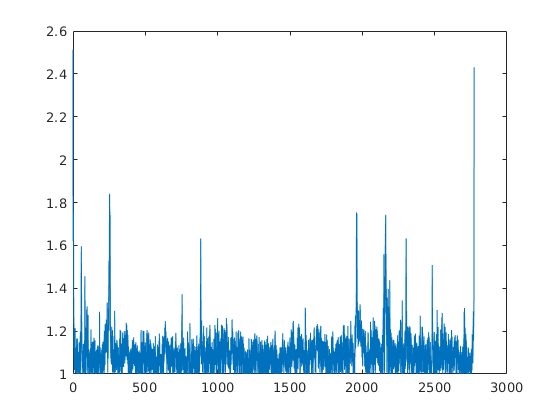

figure; plot([1:length(mot_filt)]/400,envelope(mot_filt))

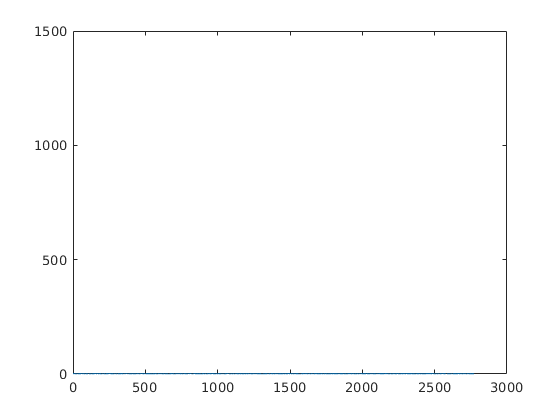

hold on;
yline(1500)

whiskEpochs = experiment.Cams.whsiking.csv_aligned_frames(mot_filt(1:length(experiment.Cams.whsiking.csv_aligned_frames)) > 1550);

whiskMat = ones(length(whiskEpochs),300).*[1:300]

whiskMat =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50
     1     2     3     4     5     6     7     8     9    10    11    12    13    14  

whiskMat = whiskMat + whiskEpochs

whiskMat =   -311  -310  -309  -308  -307  -306  -305  -304  -303  -302  -301  -300  -299  -298  -297  -296  -295  -294  -293  -292  -291  -290  -289  -288  -287  -286  -285  -284  -283  -282  -281  -280  -279  -278  -277  -276  -275  -274  -273  -272  -271  -270  -269  -268  -267  -266  -265  -264  -263  -262
  -234  -233  -232  -231  -230  -229  -228  -227  -226  -225  -224  -223  -222  -221  -220  -219  -218  -217  -216  -215  -214  -213  -212  -211  -210  -209  -208  -207  -206  -205  -204  -203  -202  -201  -200  -199  -198  -197  -196  -195  -194  -193  -192  -191  -190  -189  -188  -187  -186  -185
  -153  -152  -151  -150  -149  -148  -147  -146  -145  -144  -143  -142  -141  -140  -139  -138  -137  -136  -135  -134  -133  -132  -131  -130  -129  -128  -127  -126  -125  -124  -123  -122  -121  -120  -119  -118  -117  -116  -115  -114  -113  -112  -111  -110  -109  -108  -107  -106  -105  -104
   -87   -86   -85   -84   -83   -82   -81   -80   -79   -78   -77   -76   -75   -74  

whiskVec = unique(reshape(whiskMat,1,[])')

whiskVec =   -311
  -310
  -309
  -308
  -307
  -306
  -305
  -304
  -303
  -302


% Divide the neurons to conditions and cross with whisking epochs
experiment.conditionVector = experiment.getConVector(whiskVec)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


experiment.Units.perCondition = experiment.unitTimesCondition(whiskVec)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


experiment.Units.perCondition.FR = getFR(experiment)

experiment =   auditory_ephys_exp with properties:

           experiment_ID: 'FVB110_600'
                Pathways: [1×1 struct]
        digital_channels: [1×1 struct]
         analog_channels: [1×1 struct]
    artifacts_parameters: [1×1 struct]
     experiment_metadata: [1×1 struct]
                   Units: [1×1 struct]
              Conditions: [1×1 struct]
                    Cams: [1×1 struct]
                      SF: 30000
                   color: [1×1 struct]
            sound_events: [1×1 struct]
         predictionModel: []
                   PSTHs: []
          predictedSound: []
            evokedEvents: [1×1 struct]
         conditionVector: [1×1 struct]


allUnits = [experiment.Units.perCondition.good.alum.FR;experiment.Units.perCondition.mua.alum.FR];
allUnits(:,2) = [experiment.Units.perCondition.good.muted.FR;experiment.Units.perCondition.mua.muted.FR];
allUnits(:,3) = [experiment.Units.perCondition.good.non.FR;experiment.Units.perCondition.mua.non.FR];

allUnits = allUnits./([experiment.Units.perCondition.FR.good,experiment.Units.perCondition.FR.mua]')

allUnits =     1.1040    0.9995    0.9925
    1.0264    0.9920    0.9854
    0.9910    1.0356    1.1166
    1.0717    1.0221    1.0351
    0.8496    0.9900    1.0387
    0.8694    1.0327    1.0722
    1.0975    0.8121    0.7861
    0.8715    1.1117    1.2617
    0.9242    0.9868    0.9281
    1.4168    0.9241    0.8857


experiment.Units.perCondition.allNorm = allUnits;

%save exp 
save('FVB108_986.mat','experiment')